# Práctica 3

Integrantes:

- Altamirano Vega Jesús Mario 

- Carrillo Escamilla Ximena Donaji

- Nava Zamora Braulio César  

- Sosa Villaseñor Carlos Daniel

### Objetivos

- Implementar operaciones de conjuntos difusos, utilizando MATLAB

- Implementar transformaciones de conjuntos difusos, utilizando MATLAB

### Introducción

Un conjunto es una colección de objetos. Puede ser definido enumerando a sus miembros, o describiendo las características distintivas que cumplen todos sus elementos. En un conjunto "tradicional", un elemento pertenece a un conjunto dado o bien no pertenece. En cambio, un conjunto difuso permite valores intermedios de pertenencia. Los conjuntos difusos permiten formalizar expresiones lingüísticas que típicamente contienen algún grado de ambigüedad, es decir, proveen un método para expresar matemáticamente conceptos tales como "alto", "frío", "rápido", etc., que son bastamente usados, pero que por esencia no son precisos. Incluso conceptos netamente ingenieriles que tienen una definición numérica precisa son usados muchas veces como criterios que se acercan más a un número difuso. Por ejemplo, la correlación de dos señales, o dos funciones, puede ser normalizada para que su rango esté entre 0 y 1. Así, al explicar el valor de correlación a otra persona, es usual utilizar expresiones como "estos datos tienen una baja correlación", por ejemplo 0,1, o una "alta" correlación, por ejemplo 0,88. Otro ejemplo es la amortiguación de un sistema mecánico. Se habla de sistemas más o menos amortiguados, dándole un sentido a la noción de "la razón de amortiguación efectiva del sistema es de 0,25" como "el sistema es levemente amortiguado”. En conjuntos difusos, la ambigüedad existente en expresiones lingüísticas se expresa en el concepto de grado de membresía.

Un ejemplo de un conjunto difuso es el siguiente: sea U el conjunto de todos los valores de edad humana posibles (por ejemplo entre 0 y 120 años), y A el conjunto de los que llamamos años de la “juventud”, como un concepto intermedio entre los conceptos de “infancia” y “adultez joven”. Así podríamos afirmar que la edad de 21 años representa a los años de la “juventud”, 13 años es más cercano al concepto de “infancia”, y 30 años es más bien “adultez joven”. Así, una posibilidad de traducir y representar el conjunto A se muestra en la Figura 1.2; su función de membresía toma valores entre 0 y 1 de acuerdo al elemento de A que se evalúe. 

Con conjuntos difusos se pueden traducir valores lingüísticos a un programa computacional. Estas traducciones son particularmente importantes tanto en controladores de procesos como en sistemas expertos, en que es necesario programar instrucciones que son básicamente reglas prácticas (inglés: “rules of thumb”). Mediante lógica difusa es posible interpretar en forma matemática temas tan complejos como, por ejemplo, “si el aumento del desempleo es grande, y el aumento de las quiebras es grande, aunque el producto geográfico bruto haya caído levemente, es claramente demostrable que hay recesión.” Básicamente, el grado de membresía es subjetivo. Es un asunto de definición más que de medición. Los humanos poseen una gran habilidad para asignar grados de membresía a objetos determinados, sin un entendimiento consciente de cómo llegamos a ese valor. Por ejemplo, un alumno en un curso no tendrá mayor dificultad para asignarle al profesor un grado de membresía en el conjunto difuso de los buenos profesores.

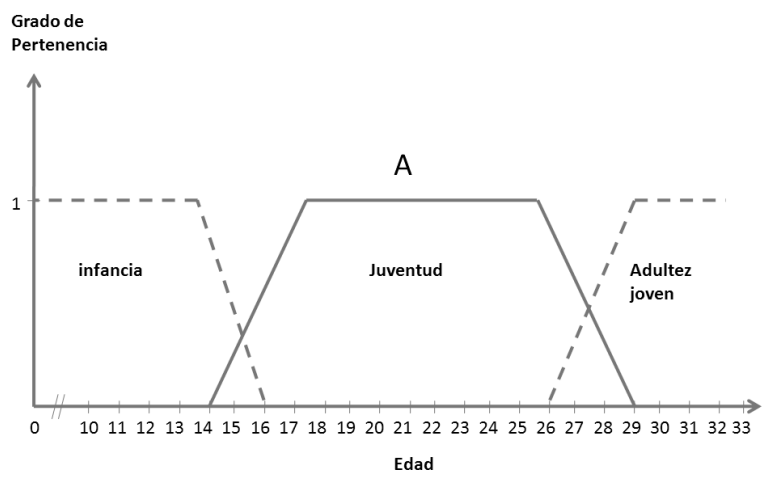

### Desarrollo

#### Problema 1

Investiga la expresión matemática para la función  smf y la función psigmf. Reporta dichas expresiones

La función smf tiene la siguiente expresión 


$$f\left(x;a,b\right)=\left\lbrack \begin{array}{c}
0,\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;x\le a\\
2{\left(\frac{x-a}{b-a}\right)}^2 ,\;\;\;\;\;\;\;\;\;a\le x\le \frac{a+b}{2}\\
1-2{\left(\frac{x-b}{b-a}\right)}^2 ,\;\;\;\frac{a+b}{2}\le x\le b\\
1,\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;x\ge b
\end{array}\right\rbrack$$


La función psigmf tiene la siguiente expresión


$$f\left(x;a_k ,c_k \right)=\frac{1}{1+e^{-a_k \left(x-c_k \right)} }$$


#### Problema 2

Cree una función en matlab que reciba como argumentos de entrada el dominio y el rango de una función de membresía, esta función debe crear la grafica del conjunto difuso con una edición de tu preferencia (no queremos repetir los códigos para gráficar cada vez que se quiera visualizar un conjunto difuso, como se ha visto previamente).

Prueba el código con las dos funciones del problema anterior, los parámetros que debes utilizar  (debes investigar) son los que se usan en el ejemplo de la práctica. 

Se espera esta sección dos llamadas a la función con las dos gráficas respectivas. 

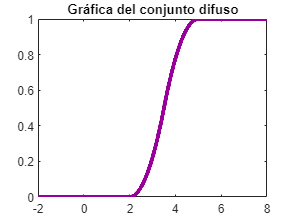

x = -2:0.01:8;
y = smf(x,[2 5]);
plot(x, y, 'color', [0.6 0 0.6], 'LineWidth', 3);
title('Gráfica del conjunto difuso');


x = -5:0.01:5;
y = psigmf(x,[-2 3 1 4]);
plot(x, y, 'color', [0.6 0 0.6], 'LineWidth', 3);
title('Gráfica del conjunto difuso');

#### Problema 3

Repite el problema anterior pero para conjuntos difusos en tiempo discreto.  

Prueba esta función con los conjuntos difusos (A, B) de la imagen 5 (OperDif5). de las notas *NO2. Operaciones difusas que se encuentran en* la página del curso.

Se espera esta sección dos llamadas a la función con las dos gráficas respectivas.

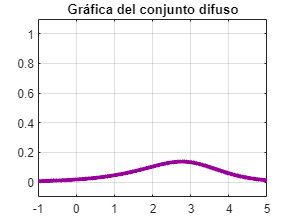

x = 1:0.5:3;
A = [1 .75 .3 .15 0];
B = [1 .6 .2 .1 0];
grid on;
axis([-1,5,-0.1,1.1]);

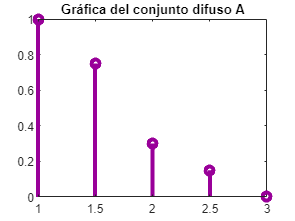

stem(x,A, 'color', [0.6 0 0.6],'LineWidth', 3)
title('Gráfica del conjunto difuso A')

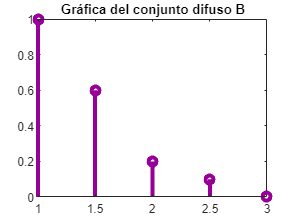


stem(x,B, 'color', [0.6 0 0.6],'LineWidth', 3)
title('Gráfica del conjunto difuso B')

#### Problema 4

Elabora una función que reciba el conjunto dominio x y el rango A de un conjunto difuso. Un parámetro adicional que indique el tipo de complemento que se quiere hacer (estándar, Sugeno, Yager). La función debe regresar el rango de valores del conjunto resultante C. Además de imprimir una figura (2 por 1) donde se muestren las grafica de los dos conjunto involucrados.

Prueba esta función con el inciso a) de la imagen 4 (OperDif4). de las notas *NO2. Operaciones difusas que se encuentran en* la página del curso. Para esto:

- Reporta los tres tipos de complementos (si no puedes implentar esto es una solo función crea tres funciones de complemento difuso)

- Combina las herramientas que ya tienes desarrolladas (de ser posible) para mostrar una gráfica con los tres tipos de complementos o desarrolla esta gráfica sin utilizar tus herramientas

En esta sección se espera tres llamadas a la función y un código para generar la cuarta gráfica. 

Complemento Estandar


C =          0    0.2500    0.7000    0.8500    1.0000


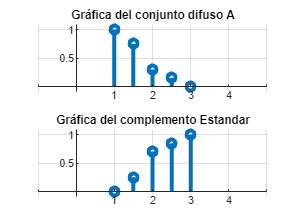

x=[1 1.5 2.0 2.5 3.0];
A=[1 0.75 0.3 0.15 0];

complemento1(x,A,1,0.5)

Complemento Sugeno


C =          0    0.1818    0.6087    0.7907    1.0000


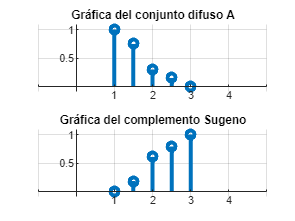

complemento1(x,A,2,0.5)

complemento1(x,A,3,1.5)

Complemento Yager


C =          0    0.4971    0.8872    0.9609    1.0000


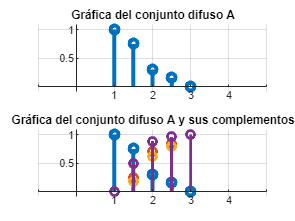


C1=1-A;
C2=(1-A)./(1+0.5.*A);
C3=(1-A.^1.5).^(1/1.5);
    stem(x,A,'LineWidth',3);
    grid on
    axis([-1,5,-0.1,1.1])
    title('Gráfica del conjunto difuso A y sus complementos')
    h = gca;                             % ejes actuales
    h.XAxisLocation = "origin";          % eje en el origen
    h.YAxisLocation = "origin";          % eje en el origen
    h.Box = "off"; 
    hold on
    stem(x,C1,'LineWidth',2);
    stem(x,C2,'LineWidth',2);
    stem(x,C3,'LineWidth',2);
    hold off

#### Problema 5

Elabora una función que reciba el conjunto dominio x, el rango A, el rango B, de dos conjunto difusos. Un parámetro adicional que indique el tipo de intersección que se quiere hacer (míninimo, producto algebraico, producto acotado). La función debe regresar el rango de valores del conjunto resultante C. Además de imprimir una figura (3 por 1) donde se muestren las grafica de los tres conjunto involucrados.

Prueba esta función con el inciso c) de la imagen 4 (OperDif4). de las notas *NO2. Operaciones difusas que se encuentran en* la página del curso. Para esto:

- Reporta los tres tipos de intersecciones

- Combina las herramientas que ya tienes desarrolladas (de ser posible) para mostrar una gráfica con los tres tipos de intersecciones o desarrolla esta gráfica sin utilizar tus herramientas

En esta sección se espera tres llamadas a la función y un código para generar la cuarta gráfica. 

Minimo


C =     1.0000    0.6000    0.2000    0.1000         0


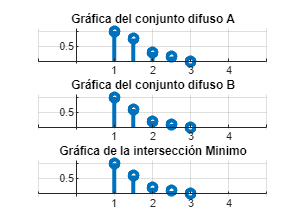

x=[1 1.5 2.0 2.5 3.0];
A=[1 0.75 0.3 0.15 0];
B=[1 0.6 0.2 0.1 0];

interseccion1(x,A,B,1)

Producto algebraico


C =     1.0000    0.4500    0.0600    0.0150         0


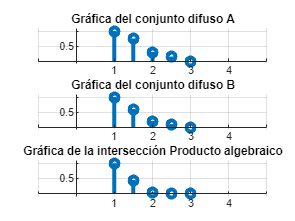

interseccion1(x,A,B,2)

interseccion1(x,A,B,3)

Producto acotado


C =     1.0000    0.3500         0         0         0


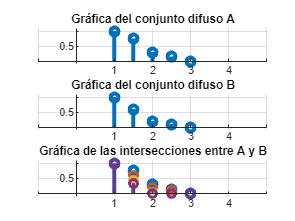


C1=min(A,B);
C2=A.*B;
C3=max(0,A+B-1);

stem(x,A,'LineWidth',3);
    grid on
    axis([-1,5,-0.1,1.1])
    title('Gráfica de las intersecciones entre A y B')
    h = gca;                             % ejes actuales
    h.XAxisLocation = "origin";          % eje en el origen
    h.YAxisLocation = "origin";          % eje en el origen
    h.Box = "off"; 
    hold on
    stem(x,C1,'LineWidth',2);

    stem(x,C2,'LineWidth',2);

    stem(x,C3,'LineWidth',2);
    hold off

#### Problema 6

Elabora una función que reciba el conjunto dominio x, el rango A, el rango B, de dos conjunto difusos. Un parámetro adicional que indique el tipo de unión que se quiere hacer (máximo, suma algebraica, suma acotada). La función debe regresar el rango de valores del conjunto resultante C. Además de imprimir una figura (3 por 1) donde se muestren las grafica de los tres conjunto involucrados.

Prueba esta función con el inciso d) de la imagen 4 (OperDif4). de las notas *NO2. Operaciones difusas que se encuentran en* la página del curso. Para esto:

- Reporta los tres tipos de uniones

- Combina las herramientas que ya tienes desarrolladas (de ser posible) para mostrar una gráfica con los tres tipos de uniones o desarrolla esta gráfica sin utilizar tus herramientas

En esta sección se espera tres llamadas a la función y un código para generar la cuarta gráfica. 

Maximo


C =     1.0000    0.7500    0.3000    0.1500         0


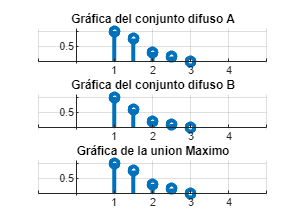

x=[1 1.5 2.0 2.5 3.0];
A=[1 0.75 0.3 0.15 0];
B=[1 0.6 0.2 0.1 0];

union1(x,A,B,1)

Suma algebraica


C =     1.0000    0.9000    0.4400    0.2350         0


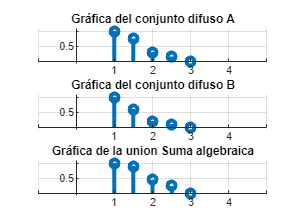

union1(x,A,B,2)

union1(x,A,B,3)

Suma acotada


C =     1.0000    1.0000    0.5000    0.2500         0


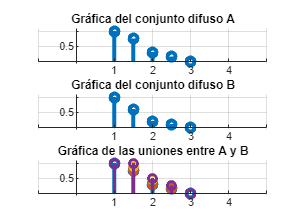


C1=max(A,B);
C2=A+B-A.*B;
C3=min(1,A+B);

stem(x,A,'LineWidth',3);
    grid on
    axis([-1,5,-0.1,1.1])
    title('Gráfica de las uniones entre A y B')
    h = gca;                             % ejes actuales
    h.XAxisLocation = "origin";          % eje en el origen
    h.YAxisLocation = "origin";          % eje en el origen
    h.Box = "off"; 
    hold on
    stem(x,C1,'LineWidth',2);

    stem(x,C2,'LineWidth',2);

    stem(x,C3,'LineWidth',2);
    hold off    

#### Problema 7

Resuleve el problema 4 para conjuntos en tiempo discreto. Prueba esta función con el inciso a) de la imagen 5 (OperDif5). 

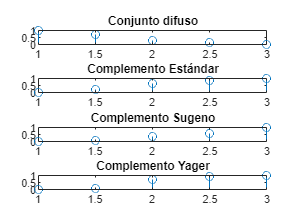

dominio = 1:0.5:3;
rango = [1,0.75,0.3,0.15,0];
p7(dominio,rango);

#### Problema 8

Resuleve el problema 5 para conjuntos en tiempo discreto. Prueba esta función con el inciso c) de la imagen 5 (OperDif5). 

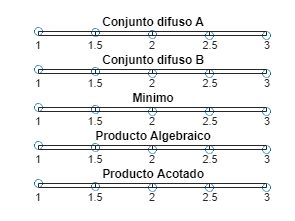

dominio = 1:0.5:3;
rangoA = [1 0.75 0.3 0.15 0];
rangoB=[1 0.6 0.2 0.1 0];
discreto = p8(dominio, rangoA,rangoB);

#### Problema 9

Resuleve el problema 6 para conjuntos en tiempo discreto. Prueba esta función con el inciso d) de la imagen 5 (OperDif5). 

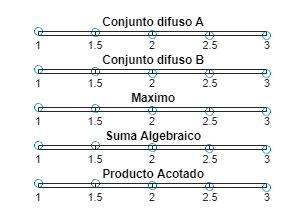

d = 1:0.5:3;
rA = [1 0.75 0.3 0.15 0];
rB=[1 0.6 0.2 0.1 0];
p9(d,rA,rB);

#### Problema 10

Implemente tres funciones,  para calcular las siguientes funciones de membresia

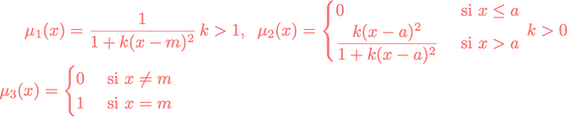

Los párametros que no muestras restricción pueden tener cualquier numero real como argumento, la función debe ser capaz de evaluar vectores de cualquier dimensión. La función $\mu_3
$ recibe el nombre de singleton

Grafique las funciones para los siguintes parámetros (con las herramientas ya construidas)

(a) $$\mu_1(x)\,con \, m=1,\,k=2$, (b) $\mu_1(x)\,con \, m=2,\,k=4$$


$$(c) \mu_2(x)\,con\, a=1,\,k=2, (d) \mu_2(x)\,con\, a=2\,k=4$$



$$(e) \mu_3(x)\,con\, m=2$$


Para ello proponga el dominio x. Se esperan 5 gráficas con el código correspndiente para generarlas.

#### Problema 11

Implemente una gráfica donde indique ejemplos especificos para ilustrar

 

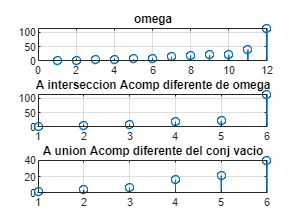

ohm = [2,3,4,5,7,10,16,19,21,22,40,115];
A1=[2,4,10,16,22,40];
An=[3,5,7,19,21,115];

a1= max(A1,An);
b1= min(A1,An);

figure
subplot(3,1,1)
stem(ohm,'LineWidth',1);
grid on
title('omega')
subplot(3,1,2)
stem(a1,'LineWidth',1);
grid on
title('A interseccion Acomp diferente de omega')
subplot(3,1,3)
stem(b1,'LineWidth',1);
grid on
title('A union Acomp diferente del conj vacio')

#### Problema 12

Escoja tres conjuntos difusos $A,B,C$ con dominuo continuo. La elección debe ser de tal forma que la itersección de B con A y de B con C sea no vacia (esto solo es solo para visulizar la operación, y solo para eso)

 verifique las siguientes propiedades

 

Para la verificación, elabore la gráfica de los conjuntos de cada lado de la igualdad y posteriormente observe que el resultado gráfico es el mismo. 

No es necesario incluir conclusiones en esta práctica, si lo considera necesario puede incluir apéndices, no olvide incluir sus referencias. 

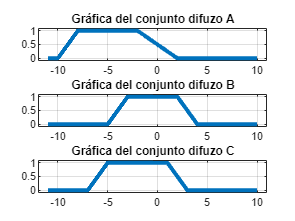

xx = -11:0.1:10;
AA = trapmf(xx,[-10 -8 -2 2]);
BB = trapmf(xx,[-5 -3 2 4]);
CC = trapmf(xx,[-7 -5 1 3]);                       
figure
subplot(3,1,1)
plot(xx,AA,'LineWidth',3);
grid on
axis([-12,11,-0.1,1.1])
title('Gráfica del conjunto difuzo A')
subplot(3,1,2)
plot(xx,BB,'LineWidth',3);
grid on
axis([-12,11,-0.1,1.1])
title('Gráfica del conjunto difuzo B')
subplot(3,1,3)
plot(xx,CC,'LineWidth',3);
grid on
axis([-12,11,-0.1,1.1])
title('Gráfica del conjunto difuzo C')

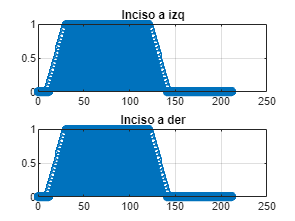


ina1= max(AA,min(BB,CC));
ina2= min(max(AA,BB),max(AA,CC));

Acomp=[setdiff(xx,AA) 0 0];
Bcomp=setdiff(xx,BB);
inb1=setdiff(xx,min(AA,BB));
inb2=max(Acomp,Bcomp);

inc1=setdiff(xx,max(AA,BB));
inc2=min(Acomp,Bcomp);

figure
subplot(2,1,1)
stem(ina1,'LineWidth',1);
grid on
title('Inciso a izq')
subplot(2,1,2)
stem(ina2,'LineWidth',1);
grid on
title('Inciso a der')

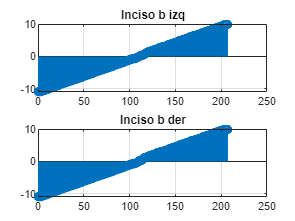


figure
subplot(2,1,1)
stem(inb1,'LineWidth',1);
grid on
title('Inciso b izq')
subplot(2,1,2)
stem(inb2,'LineWidth',1);
grid on
title('Inciso b der')

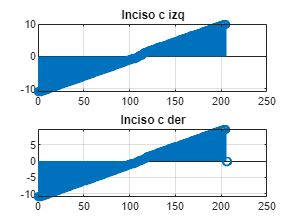


figure
subplot(2,1,1)
stem(inc1,'LineWidth',1);
grid on
title('Inciso c izq')
subplot(2,1,2)
stem(inc2,'LineWidth',1);
grid on
title('Inciso c der')

### Apéndice

function [C] = p7(dominioX,rangoA)
%Negación estándar
C = rangoA;
figure;
subplot(4,1,1);
stem(dominioX,C);
title ('Conjunto difuso');
ylim([0 1.05]);
%------------------------
standar = 1-C;
subplot(4,1,2);
stem(dominioX, standar); 
title('Complemento Estándar');
ylim([0 1.05]);

%Negación con Sugeno
s = 2.5;
sugeno = (1-C)./(1+(s.*C));
subplot(4,1,3);
stem(dominioX,sugeno);
title('Complemento Sugeno');
ylim([0 1.05]);

%Negacion con Yager
w = 2.5;
yager = (1-C).^(C.*w);
subplot(4,1,4);
stem(dominioX,yager);
title('Complemento Yager')
ylim([0,1.05]);
end

function [C] = p8(dominioX, rangoA,rangoB)

A=rangoA;
B=rangoB;
minimo=min(A,B);
c=minimo;
figure;
subplot(5,1,1);
stem(dominioX, A); title('Conjunto difuso A');
ylim([0 1.05]);
subplot(5,1,2);
stem(dominioX, B); title('Conjunto difuso B');
ylim([0 1.05]);
subplot(5,1,3);
stem(dominioX, minimo); title('Minimo');
ylim([0 1.05]);
producto_Algebraico = A.*B;
C = producto_Algebraico;
subplot(5,1,4);
stem(dominioX, producto_Algebraico); title('Producto Algebraico');
ylim([0 1.05]);
V = 0.*dominioX;
X = 1+(0.*dominioX);
D = A+B-X;
producto_Acotado = max(V, D);
C = producto_Acotado;
subplot(5,1,5);
stem(dominioX, producto_Acotado); title('Producto Acotado');
ylim([0 1.05]);

end

function [C] = p9(dominioX, rangoA, rangoB, ~)

A=rangoA;
B=rangoB;
maximo = max(A, B);
C = maximo;
figure;
subplot(5,1,1);
stem(dominioX, A); title('Conjunto difuso A');
ylim([0 1.05]);
subplot(5,1,2);
stem(dominioX, B); title('Conjunto difuso B');
ylim([0 1.05]);
subplot(5,1,3);
stem(dominioX, maximo); title('Maximo');
ylim([0 1.05]);
suma_algebraica = (A+B)-(A.*B);
C = suma_algebraica;
subplot(5,1,4);
stem(dominioX, suma_algebraica); title('Suma Algebraico');
ylim([0 1.05]);
producto_Acotado = min(1, A+B);
C = producto_Acotado;
subplot(5,1,5);
stem(dominioX, producto_Acotado); title('Producto Acotado');
ylim([0 1.05]);

end


function graficar(x,y,z)
   figure 
   if z==1 %Conjunto continuo
    plot(x,y,'m',"LineWidth",.9) 
   end
   if z==2 %Conjunto discreto
     stem(x,y,'Color','#7E2F8E','LineWidth',3);
   end
    grid on
    h = gca;                             % ejes actuales
    h.XAxisLocation = "origin";          % eje en el origen
    h.YAxisLocation = "origin";          % eje en el origen
    h.Box = "off";
  end
function complemento1(x,A,op,sw)
%x->Dominio
%A->Rango de A
%op->opcion
%sw->valor de s o w segun sea el caso
switch op
    case 1
        disp("Complemento Estandar");
        P=" Estandar";
        C=1-A;
    case 2
        disp("Complemento Sugeno");
        P=" Sugeno";
        C=(1-A)./(1+sw.*A);
    case 3
        disp("Complemento Yager");
        P=" Yager";
        C=(1-A.^sw).^(1/sw);
    otherwise
        disp("Opcion no valida")
end
    C
    figure
    subplot(2,1,1)
    stem(x,A,'LineWidth',3);
    grid on
    axis([-1,5,-0.1,1.1])
    title('Gráfica del conjunto difuso A')
    h = gca;                           
    h.XAxisLocation = "origin";         
    h.YAxisLocation = "origin";         
    h.Box = "off"; 

    subplot(2,1,2)
    stem(x,C,'LineWidth',3);
    grid on
    axis([-1,5,-0.1,1.1])
    title('Gráfica del complemento'+P)
    h = gca;                            
    h.XAxisLocation = "origin";        
    h.YAxisLocation = "origin";          
    h.Box = "off"; 
    
end
function  interseccion1(x,A,B,op)
%x->Dominio
%A->Rango de A
%B->Rango de B
%op->opcion


switch op
    case 1
        disp("Minimo");
        P=" Minimo";
        C=min(A,B);
    case 2
        disp("Producto algebraico");
        P=" Producto algebraico";
        C=A.*B;
    case 3
        disp("Producto acotado");
        P=" Producto acotado";
        C=max(0,A+B-1);
    otherwise
        disp("Opcion no valida")
end
    C
    figure
    subplot(3,1,1)
    stem(x,A,'LineWidth',3);
    grid on
    axis([-1,5,-0.1,1.1])
    title('Gráfica del conjunto difuso A')
    h = gca;                             
    h.XAxisLocation = "origin";         
    h.YAxisLocation = "origin";         
    h.Box = "off"; 
    
    subplot(3,1,2)
    stem(x,B,'LineWidth',3);
    grid on
    axis([-1,5,-0.1,1.1])
    title('Gráfica del conjunto difuso B')
    h = gca;                            
    h.XAxisLocation = "origin";        
    h.YAxisLocation = "origin";         
    h.Box = "off"; 

    subplot(3,1,3)
    stem(x,C,'LineWidth',3);
    grid on
    axis([-1,5,-0.1,1.1])
    title('Gráfica de la intersección'+P)
    h = gca;                             % ejes actuales
    h.XAxisLocation = "origin";          % eje en el origen
    h.YAxisLocation = "origin";          % eje en el origen
    h.Box = "off"; 
    
    
end

function  union1(x,A,B,op)
%x->Dominio
%A->Rango de A
%B->Rango de B
%op->opcion
switch op
    case 1
        disp("Maximo");
        P=" Maximo";
        C=max(A,B);
    case 2
        disp("Suma algebraica");
        P=" Suma algebraica";
        C=A+B-A.*B;
    case 3
        disp("Suma acotada");
        P=" Suma acotada";
        C=min(1,A+B);
    otherwise
        disp("Opcion no valida")
end
    C
    figure
    subplot(3,1,1)
    stem(x,A,'LineWidth',3);
    grid on
    axis([-1,5,-0.1,1.1])
    title('Gráfica del conjunto difuso A')
    h = gca;                            
    h.XAxisLocation = "origin";         
    h.YAxisLocation = "origin";         
    h.Box = "off"; 
    
    subplot(3,1,2)
    stem(x,B,'LineWidth',3);
    grid on
    axis([-1,5,-0.1,1.1])
    title('Gráfica del conjunto difuso B')
    h = gca;                             
    h.XAxisLocation = "origin";          
    h.YAxisLocation = "origin";         
    h.Box = "off"; 

    subplot(3,1,3)
    stem(x,C,'LineWidth',3);
    grid on
    axis([-1,5,-0.1,1.1])
    title('Gráfica de la union'+P)
    h = gca;                             
    h.XAxisLocation = "origin";         
    h.YAxisLocation = "origin";          
    h.Box = "off"; 
    
    
end

### Referencias